# **History-Dependent Nonlinear MATLAB Material in a Cyclic Pushover**

This notebook places a one-dimensional elastoplastic MATLAB material inside a regular OpenSees zeroLength element. A progressively increasing cyclic displacement history drives elastic loading, yielding, unloading, reverse yielding, and repeated plastic cycles.

The material uses linear isotropic hardening with two history variables:

* plastic strain, $\varepsilon^p$;

* accumulated plastic strain, $\alpha$.

The yield function and plastic multiplier are

$f=|\sigma_{predictor}|-(F_y+H\alpha)$

$\Delta\gamma=\frac{f}{E+H}$

The central implementation rule is that every trial response starts from committedState. Trial history is never accumulated between Newton iterations.

clc; clear; close all;

### Create the OpenSees command interface

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;
ops.wipe();

### Define material parameters and cyclic pushover amplitudes

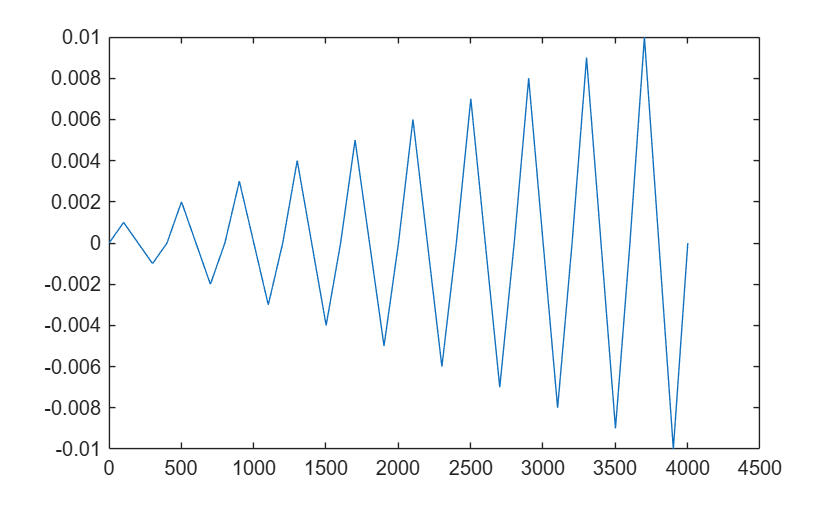

E = 200.0e3;                 % Elastic modulus
Fy = 250.0;                  % Initial yield force
H = 10.0e3;                  % Isotropic hardening modulus
materialTag = 2;
elementTag = 2;
timeSeriesTag = 2;
patternTag = 2;

yieldDeformation = Fy / E;
cyclicAmplitudes = [1.0e-3, 2.0e-3, 3.0e-3, 4.0e-3, 5.0e-3, 6.0e-3, 7.0e-3, 8.0e-3, 9.0e-3, 10.0e-3];
incrementsPerPositiveLeg = 100;
targetDisplacement = buildCyclicProtocol( ...
    cyclicAmplitudes, incrementsPerPositiveLeg);

figure("Color", "w");
plot(targetDisplacement);

### Build the zero-length structural model

ops.model("basic", "-ndm", 1, "-ndf", 1);
ops.node(1, 0.0);
ops.node(2, 0.0);
ops.fix(1, 1);

initialState = struct( ...
    "E", E, ...
    "Fy", Fy, ...
    "H", H, ...
    "plasticStrain", 0.0, ...
    "alpha", 0.0, ...
    "yielded", false);

ops.uniaxialMaterial( ...
    "MatlabUniaxialMaterial", ...
    materialTag, ...
    @isotropicHardeningCallback, ...
    initialState, ...
    E);

ops.element("zeroLength", elementTag, 1, 2, ...
    "-mat", materialTag, "-dir", 1);


### Define the reference load for displacement control

% The unit nodal load defines the reference load vector. DisplacementControl
% solves for its load factor; the cyclic protocol itself is supplied as a
% sequence of positive and negative displacement increments.

ops.timeSeries("Linear", timeSeriesTag);
ops.pattern("Plain", patternTag, timeSeriesTag);
ops.load(2, 1.0);


### Configure the nonlinear static analysis

ops.constraints("Plain");
ops.numberer("Plain");
ops.system("BandGeneral");
ops.test("NormDispIncr", 1.0e-11, 20, 0);
ops.algorithm("Newton");
displacementIncrement = diff(targetDisplacement);
firstIncrement = displacementIncrement(1);
ops.integrator("DisplacementControl", 2, 1, firstIncrement, ...
    1, firstIncrement, firstIncrement);
ops.analysis("Static");


### Run one converged OpenSees step per cyclic target

% stress and strain are queried through the zeroLength Element response API.
% They are not read from the standalone material test environment.

numberOfSteps = numel(targetDisplacement) - 1;
deformation = zeros(numberOfSteps + 1, 1);
force = zeros(numberOfSteps + 1, 1);
tangent = zeros(numberOfSteps + 1, 1);

deformation(1) = ops.nodeDisp(2, 1) - ops.nodeDisp(1, 1);
force(1) = ops.eleResponse(elementTag, "material", 1, "stress");
tangent(1) = E;

for step = 1:numberOfSteps
    % Update the controlled increment at every cyclic-pushover target.
    % Negative values naturally trace unloading and reverse loading.
    if step > 1
        increment = displacementIncrement(step);
        ops.integrator("DisplacementControl", ...
            2, 1, increment, 1, increment, increment);
    end
    status = ops.analyze(1);
    assert(status == 0, "OpenSees failed at cyclic pushover step %d.", step);

    deformation(step + 1) = ...
        ops.nodeDisp(2, 1) - ops.nodeDisp(1, 1);
    force(step + 1) = ...
        ops.eleResponse(elementTag, "material", 1, "stress");
    tangent(step + 1) = ...
        ops.eleResponse(elementTag, "material", 1, "tangent");

    assert(abs(deformation(step + 1) - targetDisplacement(step + 1)) ...
        < 1.0e-10, ...
        "DisplacementControl did not reach the target at step %d.", step);
end


### Check that both elastic and plastic branches occurred

plasticTangent = E * H / (E + H);
elasticPoints = abs(tangent - E) < 1.0e-8 * E;
plasticPoints = abs(tangent - plasticTangent) < 1.0e-8 * E;

assert(any(elasticPoints), "No elastic response points were detected.");
assert(any(plasticPoints), "No plastic response points were detected.");
assert(max(abs(deformation)) > yieldDeformation);

% Independently drive the MATLAB callback through the same committed cyclic
% history, without OpenSees, an Element, or a nonlinear solution algorithm.
[matlabForce, matlabTangent] = evaluateCallbackHistory( ...
    @isotropicHardeningCallback, targetDisplacement, initialState);

assert(max(abs(deformation - targetDisplacement)) < 1.0e-10);
assert(max(abs(force - matlabForce)) < 1.0e-8 * max(1.0, max(abs(force))));


### Plot the material hysteresis curve

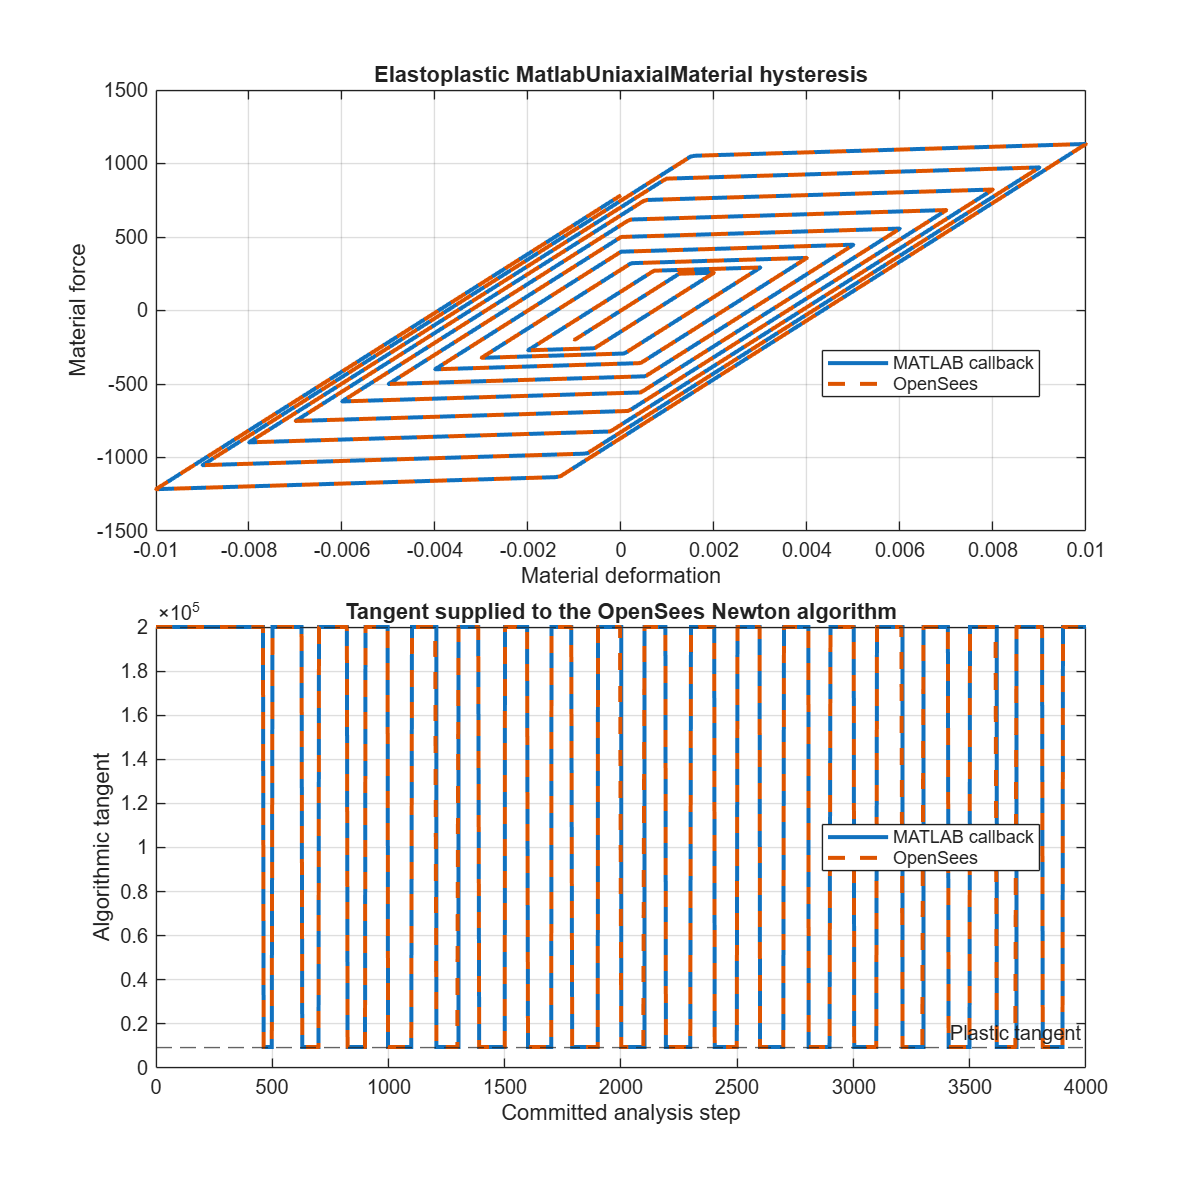

% The enclosed loops and changing yield force demonstrate path dependence.
% The figure remains in MATLAB and is not saved to disk.

figure("Color", "w", 'Position', [100, 200, 800, 800]);
tiledlayout(2, 1, "TileSpacing", "compact");

nexttile;
plot(targetDisplacement, matlabForce, "-", 'LineWidth', 2, ...
    "DisplayName", "MATLAB callback");
hold on;
plot(deformation, force, "--", "MarkerSize", 5, 'LineWidth', 2,...
    "DisplayName", "OpenSees");
grid on;
xlabel("Material deformation");
ylabel("Material force");
title("Elastoplastic MatlabUniaxialMaterial hysteresis");
legend("Location", "best");

nexttile;
h1 = stairs(0:numberOfSteps, matlabTangent, "-", 'LineWidth', 2, ...
    "DisplayName", "MATLAB callback");
hold on;
h2 = plot(0:numberOfSteps, tangent, "--", "MarkerSize", 3, 'LineWidth', 2, ...
    "DisplayName", "OpenSees");
yline(E, "--", "Elastic tangent");
yline(plasticTangent, "--", "Plastic tangent");
grid on;
xlabel("Committed analysis step");
ylabel("Algorithmic tangent");
legend([h1 h2], "Location", "best");
title("Tangent supplied to the OpenSees Newton algorithm");

ops.wipe();

### Cyclic displacement protocol helper

% One complete cycle is generated at each increasing amplitude:
% zero -> positive peak -> negative peak -> zero.

function protocol = buildCyclicProtocol(amplitudes, incrementsPerPositiveLeg)
    protocol = 0.0;
    
    for amplitude = amplitudes
        positiveBranch = linspace(0.0, amplitude, ...
            incrementsPerPositiveLeg + 1).';
        reversalBranch = linspace(amplitude, -amplitude, ...
            2*incrementsPerPositiveLeg + 1).';
        returnBranch = linspace(-amplitude, 0.0, ...
            incrementsPerPositiveLeg + 1).';
    
        protocol = [protocol; ... %#ok<AGROW>
            positiveBranch(2:end); ...
            reversalBranch(2:end); ...
            returnBranch(2:end)];
    end
end


### Direct MATLAB callback driver

% After every successful direct evaluation, trialState becomes committedState
% for the following target. This reproduces the material-point history while
% remaining independent of the OpenSees analysis.

function [force, tangent] = evaluateCallbackHistory(callback, deformation, initialState)
    numberOfPoints = numel(deformation);
    force = zeros(numberOfPoints, 1);
    tangent = zeros(numberOfPoints, 1);
    committedState = initialState;
    
    for point = 1:numberOfPoints
        action = "trial";
        if point == 1
            action = "init";
        end
        trial = struct("strain", deformation(point), "strainRate", 0.0);
        [response, trialState, status] = callback(action, trial, committedState);
        assert(status == 0, "Direct MATLAB callback evaluation failed.");
        force(point) = response.stress;
        tangent(point) = response.tangent;
        committedState = trialState;
    end
end

### Elastoplastic return-mapping callback

% If OpenSees rejects an analysis step, the returned trial state is discarded.
% A retry with a smaller increment or another algorithm begins again from the
% same committed plasticStrain and alpha.

function [response, state, status] = isotropicHardeningCallback(action, trial, committedState)
    state = committedState;
    status = 0;
    
    E = committedState.E;
    Fy = committedState.Fy;
    H = committedState.H;
    
    switch action
        case {"init", "trial"}
            % Elastic predictor based only on committed history variables.
            sigmaPredictor = E * (trial.strain - committedState.plasticStrain);
            yieldForce = Fy + H * committedState.alpha;
            yieldFunction = abs(sigmaPredictor) - yieldForce;
    
            if yieldFunction <= 0.0
                force = sigmaPredictor;
                tangent = E;
                state.yielded = false;
            else
                flowDirection = sign(sigmaPredictor);
                deltaGamma = yieldFunction / (E + H);
    
                state.plasticStrain = committedState.plasticStrain + ...
                    deltaGamma * flowDirection;
                state.alpha = committedState.alpha + deltaGamma;
                state.yielded = true;
    
                force = sigmaPredictor - E * deltaGamma * flowDirection;
                tangent = E * H / (E + H);
            end
    
            response = struct("stress", force, "tangent", tangent);
    
        otherwise
            % Current OpenSeesMEX versions invoke only init and trial. Commit and
            % rollback copy or restore the returned state entirely in C++.
            response = struct("stress", 0.0, "tangent", E);
            status = -1;
    end
end
